% x = [-0.5:0.1:0.5]*2*pi;
% y = [-0.5:0.1:0.5]*2*pi;
% z = [-0.5:0.1:0.5]*2*pi;
% [X,Y,Z] = meshgrid(x,y,z);
% 
% F1 = cos(X) + cos(Y) + cos(Z)+ t1;
% F2 = cos(X).*cos(Y).*cos(Z) - sin(X).*sin(Y).*sin(Z) + t2;
% F3 = 8*cos(X).*cos(Y).*cos(Z)+cos(2*X).*cos(2*Y).*cos(2*Z)-(cos(2*X).*cos(2*Y)+cos(2*Y).*cos(2*Z)+cos(2*Z).*cos(2*X))+t3;
% Fmerge =@(X,Y,Z) alpha1*4*F1+alpha2*4*F2+alpha3*F3;
% % fun = @(X,Y,Z)0.576*(cos(X)+cos(Y)+cos(Z)+0.146)+0.364*(cos(X).*cos(Y).*cos(Z)-sin(X).*sin(Y).*sin(Z)+-0.0547)+0.0597*(8*cos(X).*cos(Y).*cos(Z)+cos(2*X).*cos(2*Y).*cos(2*Z)-(cos(2*X).*cos(2*Y)+cos(2*Y).*cos(2*Z)+cos(2*Z).*cos(2*X))+-0.213);
% 
% v1 = Fmerge(x,y,z);
% [faces, verts] = isosurface(X+2*pi*Xc,Y-2*pi*Yc,Z-2*pi*Zc,v1,0);
% [facesc, vertsc] = isocaps(X+2*pi*Xc,Y-2*pi*Yc,Z-2*pi*Zc,v1,0);
% faces = [faces;facesc+length(verts)];
% verts = [verts;vertsc];

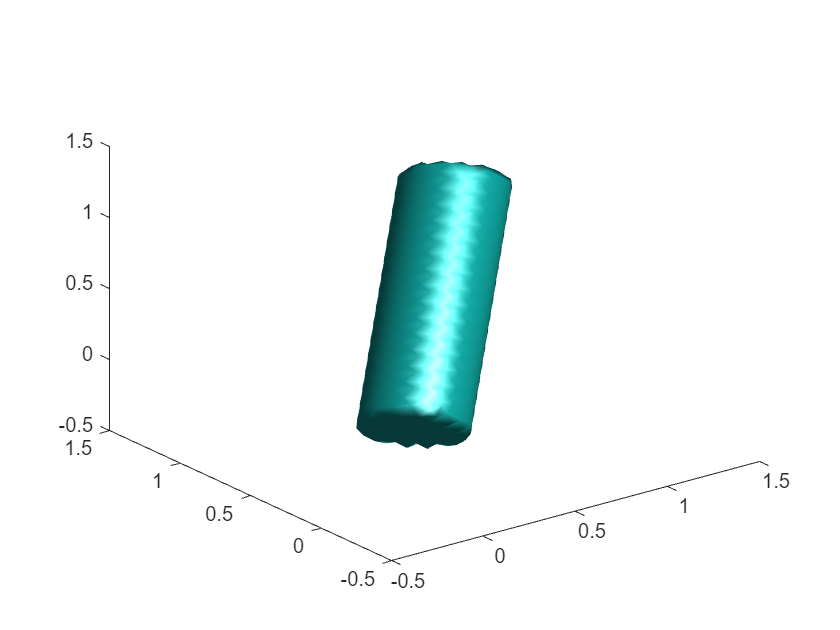

clc;clear;
tPart=0.5;
x1=0;y1=0;z1=0;
x2=1;y2=1;z2=1;


X = [-0.5:0.01:0.5]*2*pi;
Y = [-0.5:0.01:0.5]*2*pi;
Z = [-0.5:0.01:0.5]*2*pi;
[x,y,z] = meshgrid(X,Y,Z);

% FaiPart = max(Part3)
% FaiPartc = min(Part2)
x0=(x1+x2)/2;y0=(y1+y2)/2;z0=(z1+z2)/2;LPart=sqrt((x2-x1).^2+(y2-y1).^2+(z2-z1).^2);
dx2=x2-x0;dy2=y2-y0;dz2=z2-z0;
dx=x-x0;dy=y-y0;dz=z-z0;
Ld = sqrt(dx.^2+dy.^2+dz.^2);
cos_ThetaPart = sqrt(((dx*dx2+dy*dy2+dz*dz2)./(Ld*sqrt(dx2^2+dy2^2+dz2^2))).^2);
sin_ThetaPart = sqrt(1-cos_ThetaPart.^2);

FaiPartc1 =  (LPart/2)^2-(cos_ThetaPart.*Ld).^2;
FaiPartc2 =  (tPart/2)^2-(sin_ThetaPart.*Ld).^2;
% FaiParts1 =  (tpart/2)^2-(x-x1)^2+(y-y1)^2+(z-z1)^2;
% FaiParts2 =  (tpart/2)^2-(x-x2)^2+(y-y2)^2+(z-z2)^2;

FaiPartc = min(FaiPartc1,FaiPartc2);

% v1 = FaiPartc1(x,y,z);
% isosurface(x,y,z,v1,0)

% v2 = FaiPartc2(x,y,z);
% isosurface(x,y,z,v2,0)


isosurface(x,y,z,FaiPartc,0)